[XTrain,YTrain] = digitTrain4DArrayData;

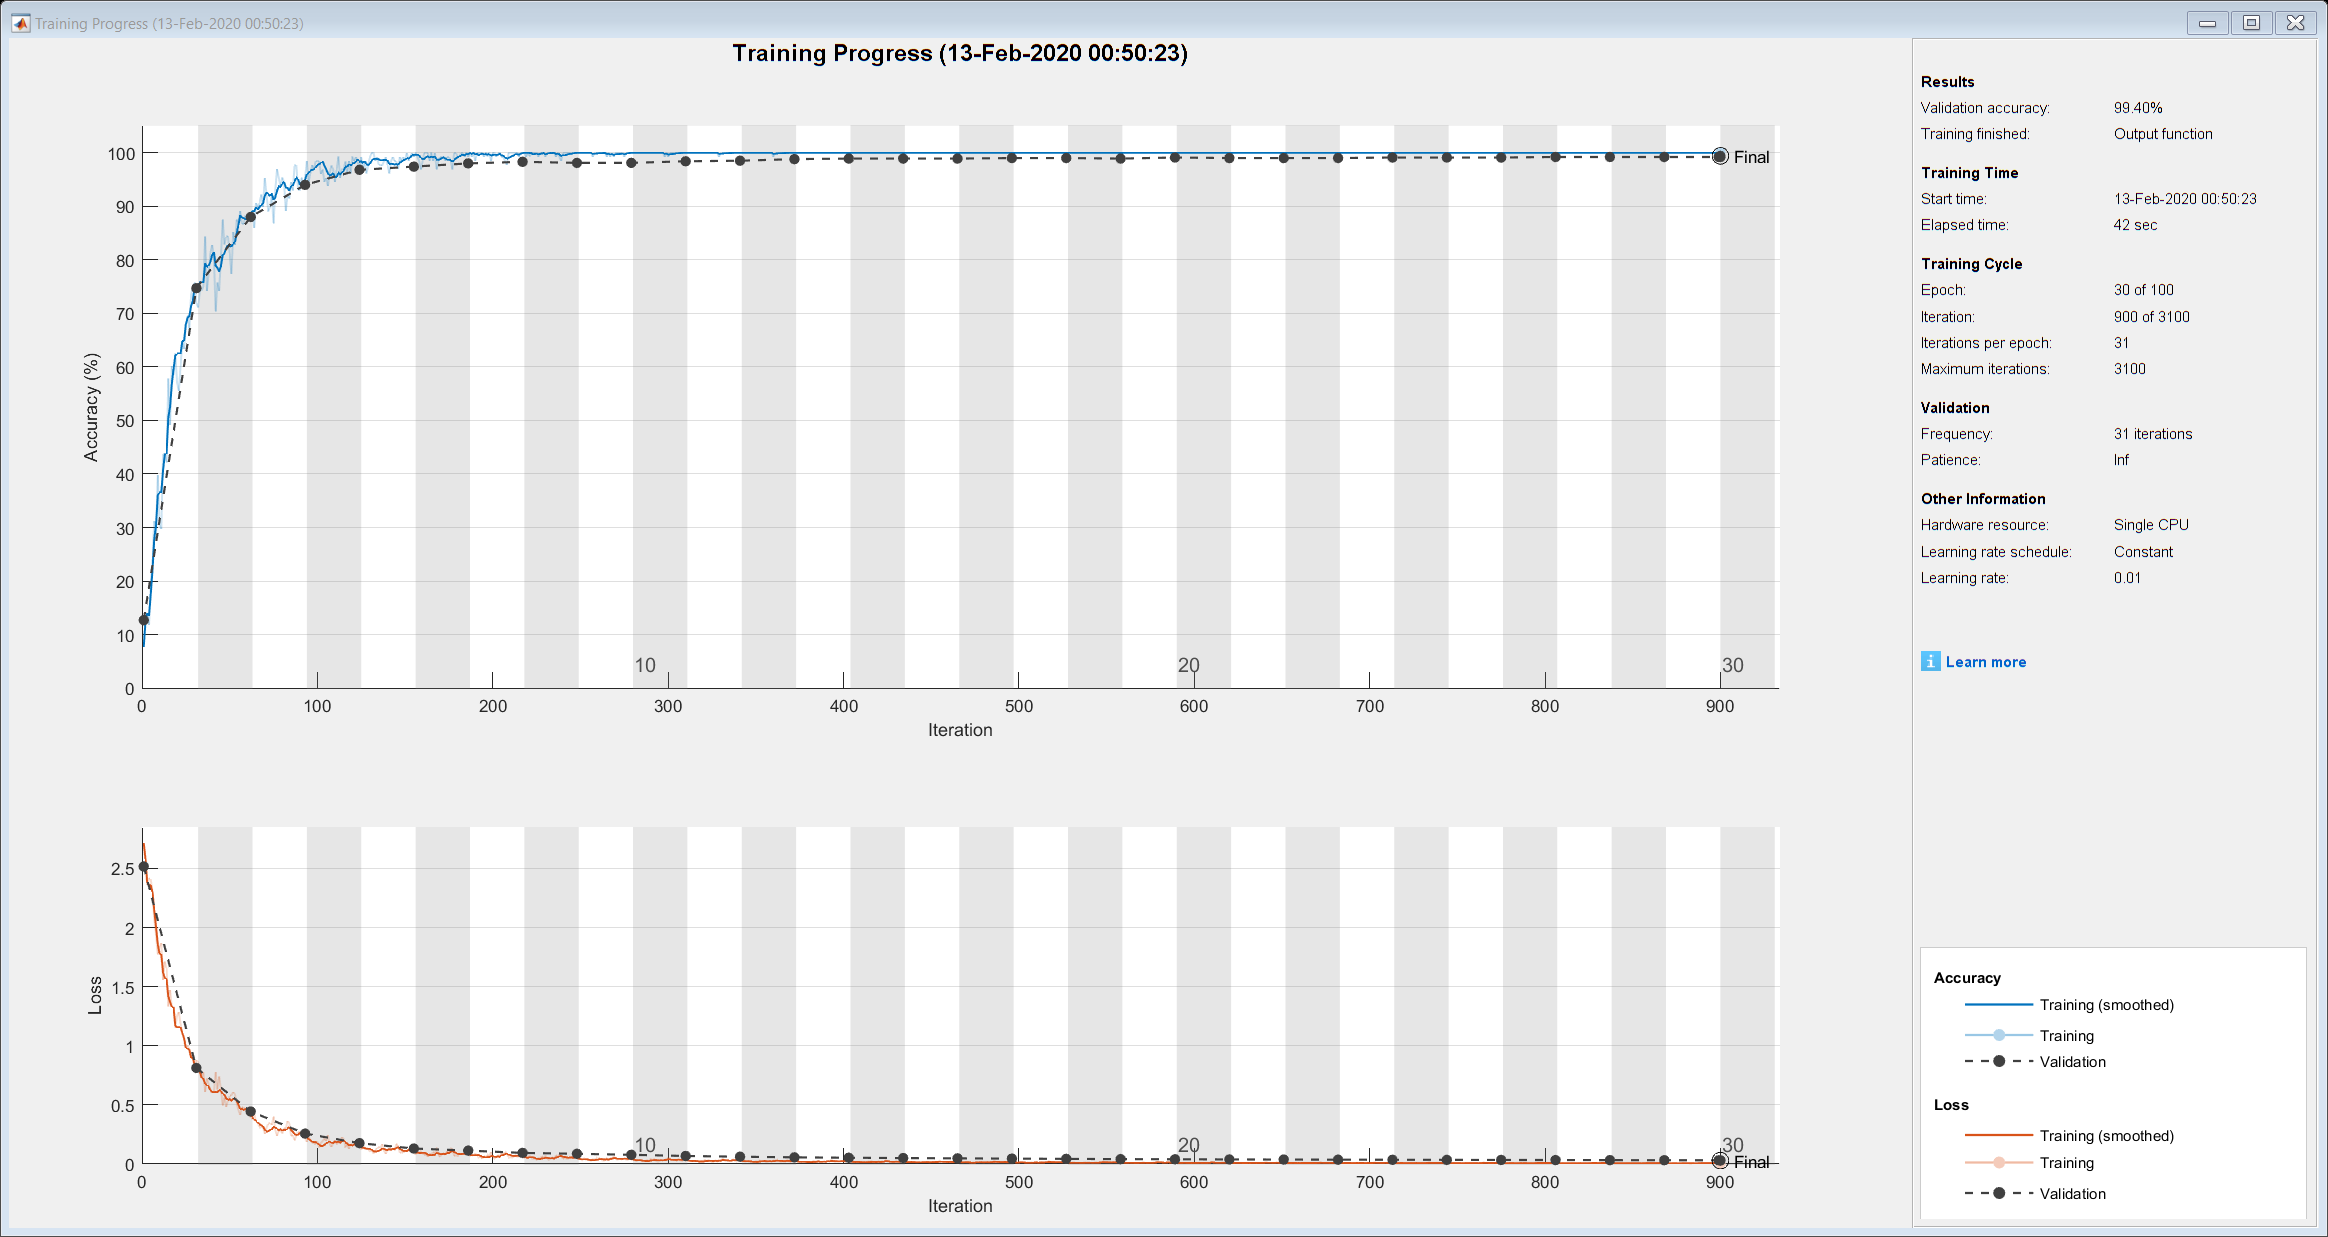

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.81% |       12.70% |       2.7155 |       2.5169 |          0.0100 |
|       1 |          31 |       00:00:03 |       71.88% |       74.70% |       0.8804 |       0.8128 |          0.0100 |
|       2 |          62 |       00:00:04 |       87.50% |       88.00% |       0.3889 |       0.4438 |          0.0100 |
|       3 |          93 |       00:00:06 |       95.31% |       94.00% |       0.2212 |   


idx = randperm(size(XTrain,4),1000);
XValidation = XTrain(:,:,:,idx);
XTrain(:,:,:,idx) = [];
YValidation = YTrain(idx);
YTrain(idx) = [];
layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer   
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];
miniBatchSize = 128;
validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'VerboseFrequency',validationFrequency, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'OutputFcn',@(info)dbStopFunction(info,3,100));
net = trainNetwork(XTrain,YTrain,layers,options);